
clear all ; 
close all ; 
clc ;



## Norm 2 of SISO systems


num = [1,-1] ; 
den = [1,2,10] ;
G = tf(num,den) ; 


#### Frequency response of G


g = @(omega) abs(squeeze(freqresp(G,omega))).^2 ;

omega_min_max = 10000 ;
omega_stamp = 0.7 ; 
omega_values = -omega_min_max:omega_stamp:omega_min_max ;

FreqNormSISO = sqrt( sum(g(omega_values) * omega_stamp ) / (2*pi) ) ; 

disp( FreqNormSISO ) 

    0.5244



#### Impulse response


T = linspace(0,5,5000) ; 
[ Y , T ] = impulse(G, T) ; 
ImpulseNormSISO = (trapz(T,abs(Y).^2))^0.5 ; 

disp(ImpulseNormSISO) ; 

    0.5244



#### State space method


[A,B,C,D] = ssdata(G) ; 

LSISO = are(A', zeros(2,2), B*B') ; 
SSNormSISO = sqrt( trace(C*LSISO*C') ) ; 

disp(SSNormSISO) ; 

    0.5244



#### True norm

TrueNormSISO = norm(G, 2) ;
disp( TrueNormSISO ) ; 

    0.5244



## Norm 2 MIMO systems 


A2 = [ 20 -27 7 ; 53 -63 13 ; -5 12 -8 ] ; 
B2 = [ 1 -1 ; -2 -1 ; -3 0 ] ; 
C2 = [ 0 0 -2 ; 1 -1 -1 ] ;
D2 = [ 0 0 ; 0 0 ] ; 

systf=tf(ss(A2,B2,C2,D2)) ;

#### Frequency response of G


G = @(omega) freqresp(systf,omega) ;

G_conj = @(omega) ctranspose(freqresp(systf,omega)) ;
tr = @(omega) trace(G_conj(omega)*G(omega)) ;

omega_min_max = 1000 ;
omega_stamp = 0.1    ; 
omega_values = -omega_min_max:omega_stamp:omega_min_max ;

integrand_values = zeros(size(omega_values));

for i = 1:length(omega_values)
    integrand_values(i) = tr(omega_values(i)) ;
end

FreqNormMIMO = sqrt( sum( integrand_values * omega_step ) / (2*pi) ) ;

disp( FreqNormMIMO ) ; 


#### State space method


LMIMO = are(A2', zeros(3,3), B2*B2') ; 
SSNormMIMO = sqrt( trace(C2*LMIMO*C2') ) ;

disp( SSNormMIMO ) ; 

    2.2818



#### True norm

TrueNormMIMO = norm(systf, 2) ; 

disp( TrueNormMIMO ) ; 

    2.2818



## print random to check view

a = 0:0.01:(4*pi) ; 
b = sin(a)

b =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0699    0.0799    0.0899    0.0998    0.1098    0.1197    0.1296    0.1395    0.1494    0.1593    0.1692    0.1790    0.1889    0.1987    0.2085    0.2182    0.2280    0.2377    0.2474    0.2571    0.2667    0.2764    0.2860    0.2955    0.3051    0.3146    0.3240    0.3335    0.3429    0.3523    0.3616    0.3709    0.3802    0.3894    0.3986    0.4078    0.4169    0.4259    0.4350    0.4439    0.4529    0.4618    0.4706


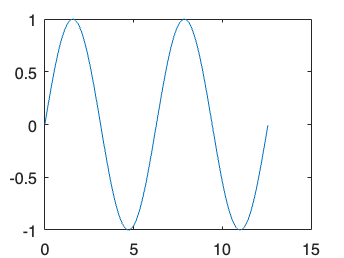


figure
plot(a, b)